# Test CNN.m

## Parameters

cnn = CNN();

N                                          = 100;   % number of data

cnn.x                                      = [];
cnn.y                                      = [];
cnn.divide_param.train_ratio               = 70/100;
cnn.divide_param.validation_ratio          = 15/100;
cnn.divide_param.test_ratio                = 15/100;

cnn.kernel_sizes                           = [
                                                10, 10, 10
                                                5, 5, 5
                                             ];
cnn.output_size                            = [2, 2, 10];

cnn.number_of_epochs                       = 100;
cnn.batch_size                             = N;
cnn.learning_rate                          = 0.001;
cnn.number_of_validations_faild            = 10;

cnn.C                                      = @CNN.quadratic_cost_function;
cnn.C_                                     = @CNN.diff_quadratic_cost_function;
cnn.s                                      = @CNN.rectifier_activation_function;
cnn.s_                                     = @CNN.diff_rectifier_activation_function;

## Neural Network

cnn.init();
cnn.make_data(N);

## Learning

sigma                                     = 10; % gaussian noise to kernels
cnn.add_noise_to_w(sigma);
cnn.add_noise_to_b(sigma);

tic();
cnn.run();
toc();

Elapsed time is 25.566212 seconds.


## Show Results

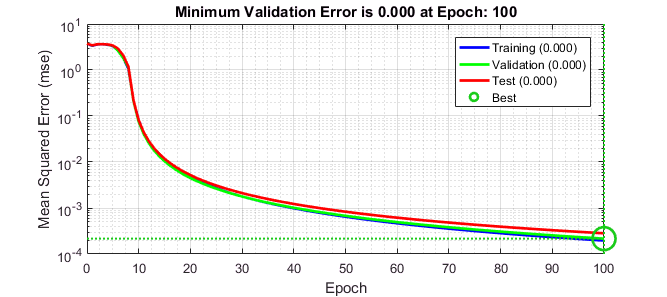

cnn.plot_total_cost_history();